%% ofdm_pilots_multipath_updated.m
% OFDM with Pilots + Multipath Channel + ZF / MMSE equalizers
% Improved: pre-generated channel per symbol, spline interpolation, save constellations
clear; clc; close all;

% ----------------- PARAMETERS -----------------
N = 64;             % subcarriers
cp = 16;            % cyclic prefix
M = 4;              % QPSK
k = log2(M);
numSymbols = 200;   % number of OFDM symbols per SNR point (reduce to 50 for faster tests)
pilotSpacing = 4;   % every 4th subcarrier is pilot
pilotValue = 1+0j;  % known pilot symbol (complex)
SNRdB_list = 0:2:20; 
rng_awgn_seed = 0;  % seed controlling AWGN baseline reproducibility

% Multipath channel parameters (tapped delay line)
L = 4;                      % number of taps
tap_delays = [0 1 3 5];     % sample delays (not used explicitly but informative)
tap_powers_db = [0 -3 -6 -9]; % relative power in dB
tap_powers = 10.^(tap_powers_db/10);
tap_powers = tap_powers / sum(tap_powers);   % normalize

% Example constellation save SNR target
constellation_save_SNR = 12;    % in dB, pick one value in SNRdB_list
save_constellation_example = true; % set false to skip saving example constellations

% Interpolation method: 'linear' or 'spline'
interp_method = 'spline';

% ----------------- PREPARE PILOTS & CHANNELS -----------------
pilot_idx = 1:pilotSpacing:N;   % pilot positions (1-based)
data_idx = setdiff(1:N, pilot_idx);

% Pre-generate channel taps for each OFDM symbol (slow fading per symbol)
rng(42); % seed for channel generation
h_table = zeros(numSymbols, L);  % each row = channel taps for symbol s
for s = 1:numSymbols
    h_table(s,:) = sqrt(tap_powers/2) .* (randn(1,L) + 1j*randn(1,L));
end

% ----------------- GENERATE BITSTREAM & SYMBOLS -----------------
totalBits = N * k * numSymbols;
bits_all = randi([0 1], totalBits, 1);       % random bits
bits_matrix_all = reshape(bits_all, k, []).'; % (N*numSymbols) x k
sym_idx_all = bi2de(bits_matrix_all, 'left-msb');   % integer symbol indices
sym_idx_matrix = reshape(sym_idx_all, N, []).';     % numSymbols x N (rows)

% Helper inline
ifft_sym = @(x) ifft(x, N);

% ----------------- PREPARE RESULTS STORAGE -----------------
ber_awgn = zeros(size(SNRdB_list));
ber_multipath_noeq = zeros(size(SNRdB_list));
ber_multipath_zf = zeros(size(SNRdB_list));
ber_multipath_mmse = zeros(size(SNRdB_list));

% For AWGN reproducibility
rng(rng_awgn_seed);

% ----------------- MAIN SNR LOOP -----------------
for si = 1:length(SNRdB_list)
    SNRdB = SNRdB_list(si);
    fprintf('Running SNR = %2d dB\n', SNRdB);
    
    % ----- Build TX time-domain for all symbols with pilots inserted -----
    tx_time = zeros(numSymbols*(N+cp),1);
    ptr = 1;
    for s = 1:numSymbols
        % Data symbols for this OFDM symbol
        tx_sym_idx = sym_idx_matrix(s,:);  % length N (row)
        data_symbols = pskmod(tx_sym_idx.', M, pi/4, 'gray');   % column N
        % Insert pilots (override those subcarriers with known complex pilotValue)
        data_symbols(pilot_idx) = pilotValue;
        % IFFT and CP
        ofdm_t = ifft_sym(data_symbols);   % column N
        tx_sig_s = [ofdm_t(end-cp+1:end); ofdm_t];  % N+cp
        tx_time(ptr:ptr+N+cp-1) = tx_sig_s;
        ptr = ptr + (N+cp);
    end
    
    % ----------------- 1) AWGN BASELINE (no multipath) -----------------
    rx_awgn = awgn(tx_time, SNRdB, 'measured');
    % RX baseline: demod symbol-by-symbol
    rx_sym_idx_all = zeros(numSymbols, N);
    ptr = 1;
    for s = 1:numSymbols
        rx_frame = rx_awgn(ptr+cp:ptr+cp+N-1);
        ptr = ptr + (N+cp);
        Rf = fft(rx_frame, N);
        rx_idx = pskdemod(Rf, M, pi/4, 'gray');
        rx_sym_idx_all(s,:) = rx_idx.';
    end
    rx_sym_idx_col = reshape(rx_sym_idx_all.',[],1);
    rx_bits_matrix = de2bi(rx_sym_idx_col, k, 'left-msb');
    rx_bits = reshape(rx_bits_matrix.', [],1);
    [~, ber_awgn(si)] = biterr(bits_all, rx_bits);
    
    % ----------------- 2) MULTIPATH (NO EQ) -----------------
    % Convolve each symbol with its channel h_table(s,:) and add AWGN
    rx_time_mp = zeros(size(tx_time));
    ptr = 1;
    for s = 1:numSymbols
        h = squeeze(h_table(s,:));
        tx_block = tx_time(ptr:ptr+N+cp-1);
        rx_block = conv(tx_block, h).';   % length N+cp+L-1
        % take first N+cp (works if max delay < cp); otherwise would need overlap-add
        rx_time_mp(ptr:ptr+N+cp-1) = rx_block(1:N+cp);
        ptr = ptr + (N+cp);
    end
    rx_time_mp = awgn(rx_time_mp, SNRdB, 'measured');
    
    % Demodulate (no equalization)
    rx_sym_idx_all = zeros(numSymbols, N);
    ptr = 1;
    for s = 1:numSymbols
        rx_frame = rx_time_mp(ptr+cp:ptr+cp+N-1);
        ptr = ptr + (N+cp);
        Rf = fft(rx_frame, N);
        rx_idx = pskdemod(Rf, M, pi/4, 'gray');
        rx_sym_idx_all(s,:) = rx_idx.';
    end
    rx_sym_idx_col = reshape(rx_sym_idx_all.',[],1);
    rx_bits_matrix = de2bi(rx_sym_idx_col, k, 'left-msb');
    rx_bits = reshape(rx_bits_matrix.', [],1);
    [~, ber_multipath_noeq(si)] = biterr(bits_all, rx_bits);
    
    % ----------------- 3) MULTIPATH + PILOT-BASED ESTIMATE + ZF/MMSE -----------------
    rx_sym_idx_all_zf = zeros(numSymbols, N);
    rx_sym_idx_all_mmse = zeros(numSymbols, N);
    ptr = 1;
    for s = 1:numSymbols
        % Convolve single symbol block with pre-generated channel h
        h = squeeze(h_table(s,:));
        tx_block = tx_time(ptr:ptr+N+cp-1);
        rx_block = conv(tx_block, h).';
        rx_block = rx_block(1:N+cp);  % truncate
        % Add AWGN
        rx_block = awgn(rx_block, SNRdB, 'measured');
        % Remove CP and FFT
        rx_frame = rx_block(cp+1:cp+N);
        Rf = fft(rx_frame, N);   % received freq-domain (column)
        
        % True frequency response (for reference)
        H_true = fft([h zeros(1, N-length(h))], N).';  % column N
        
        % Pilot-based LS estimate at pilot positions
        Yp = Rf(pilot_idx).';                % column
        Xp = pilotValue * ones(length(pilot_idx),1);
        H_p_est = Yp ./ Xp;                 % LS estimate on pilot subcarriers
        
        % Interpolate H estimate across all subcarriers
        H_est = interp1(pilot_idx, H_p_est, 1:N, interp_method, 'extrap').';  % column N
        
        % Noise variance approx (symbol energy ~1): N0 = 1 / (10^(SNR/10))
        N0 = 1/(10^(SNRdB/10));
        
        % ZF equalization
        X_hat_zf = Rf.' ./ H_est;    % column
        % MMSE equalization (frequency domain)
        X_hat_mmse = (conj(H_est) .* Rf.') ./ (abs(H_est).^2 + N0);
        
        % Demodulate
        rx_idx_zf = pskdemod(X_hat_zf, M, pi/4, 'gray');
        rx_idx_mmse = pskdemod(X_hat_mmse, M, pi/4, 'gray');
        rx_sym_idx_all_zf(s,:) = rx_idx_zf.';
        rx_sym_idx_all_mmse(s,:) = rx_idx_mmse.';
        
        % Save example constellations for first symbol at a target SNR
        if save_constellation_example && (SNRdB == constellation_save_SNR) && (s == 1)
            % MMSE
            fig1 = figure('visible','off'); plot(real(X_hat_mmse), imag(X_hat_mmse), 'o'); title('MMSE equalized constellation example'); axis equal; grid on;
            saveas(fig1, 'constellation_mmse_example.png'); close(fig1);
            % ZF
            fig2 = figure('visible','off'); plot(real(X_hat_zf), imag(X_hat_zf), 'o'); title('ZF equalized constellation example'); axis equal; grid on;
            saveas(fig2, 'constellation_zf_example.png'); close(fig2);
            % No-EQ (Rf)
            fig3 = figure('visible','off'); plot(real(Rf), imag(Rf), 'o'); title('Multipath (no EQ) constellation example'); axis equal; grid on;
            saveas(fig3, 'constellation_noeq_example.png'); close(fig3);
            % AWGN constellation: make from baseline first symbol
            % capture AWGN first symbol if available (we can reconstruct quickly)
            % Find first AWGN symbol frame (from rx_awgn)
            try
                % compute AWGN first symbol Rf_awgn
                awgn_ptr = 1;
                rx_awgn_frame = rx_awgn(awgn_ptr+cp:awgn_ptr+cp+N-1);
                Rf_awgn = fft(rx_awgn_frame, N);
                fig4 = figure('visible','off'); plot(real(Rf_awgn), imag(Rf_awgn), 'o'); title('AWGN constellation example'); axis equal; grid on;
                saveas(fig4, 'constellation_awgn_example.png'); close(fig4);
            catch
                % ignore if fails
            end
        end
        
        ptr = ptr + (N+cp);
    end
    
    % Compute BERs for ZF and MMSE
    rx_sym_idx_col_zf = reshape(rx_sym_idx_all_zf.',[],1);
    rx_bits_matrix_zf = de2bi(rx_sym_idx_col_zf, k, 'left-msb');
    rx_bits_zf = reshape(rx_bits_matrix_zf.',[],1);
    [~, ber_multipath_zf(si)] = biterr(bits_all, rx_bits_zf);
    
    rx_sym_idx_col_mmse = reshape(rx_sym_idx_all_mmse.',[],1);
    rx_bits_matrix_mmse = de2bi(rx_sym_idx_col_mmse, k, 'left-msb');
    rx_bits_mmse = reshape(rx_bits_matrix_mmse.',[],1);
    [~, ber_multipath_mmse(si)] = biterr(bits_all, rx_bits_mmse);
    
end % SNR loop

Running SNR =  0 dB
Running SNR =  2 dB
Running SNR =  4 dB
Running SNR =  6 dB
Running SNR =  8 dB
Running SNR = 10 dB
Running SNR = 12 dB


Running SNR = 14 dB
Running SNR = 16 dB
Running SNR = 18 dB
Running SNR = 20 dB


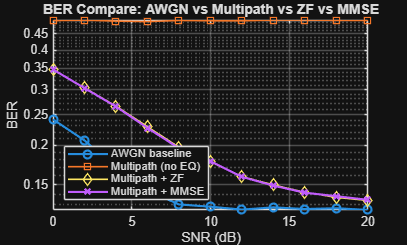


% ----------------- PLOT & SAVE RESULTS -----------------
figure;
semilogy(SNRdB_list, ber_awgn, '-o','LineWidth',1.6); hold on;
semilogy(SNRdB_list, ber_multipath_noeq, '-s','LineWidth',1.2);
semilogy(SNRdB_list, ber_multipath_zf, '-d','LineWidth',1.2);
semilogy(SNRdB_list, ber_multipath_mmse, '-x','LineWidth',1.6);
grid on; xlabel('SNR (dB)'); ylabel('BER'); title('BER Compare: AWGN vs Multipath vs ZF vs MMSE');
legend('AWGN baseline','Multipath (no EQ)','Multipath + ZF','Multipath + MMSE','Location','southwest');
saveas(gcf,'ber_compare.png');


% Save CSV: columns = [SNR, AWGN, MultipathNoEQ, MultipathZF, MultipathMMSE]
T = [SNRdB_list.' ber_awgn.' ber_multipath_noeq.' ber_multipath_zf.' ber_multipath_mmse.'];
csvwrite('ber_compare.csv', T);

fprintf('Done. Results saved: ber_compare.png and ber_compare.csv\n');

Done. Results saved: ber_compare.png and ber_compare.csv


if save_constellation_example
    fprintf('Saved constellation examples (if created): constellation_*.png\n');
end

Saved constellation examples (if created): constellation_*.png
